load WaveformData

numChannels = size(data{1},1)

numChannels = 3

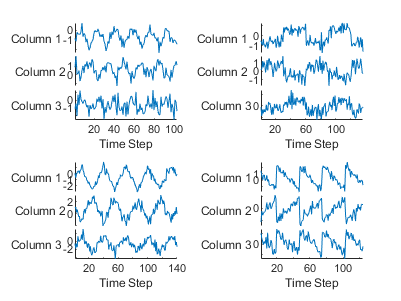



figure
tiledlayout(2,2)
for i = 1:4
    nexttile
    stackedplot(data{i}')

    xlabel("Time Step")
end

entrenamiento

numObservations = numel(data);
idxTrain = 1:floor(0.9*numObservations);
idxTest = floor(0.9*numObservations)+1:numObservations;
dataTrain = data(idxTrain);
dataTest = data(idxTest);



for n = 1:numel(dataTrain)
    X = dataTrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(:,2:end);
end


muX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);

muT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);

for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;
end
   

Crear red neuronal

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];


Especificar opciones de entrnamiento 

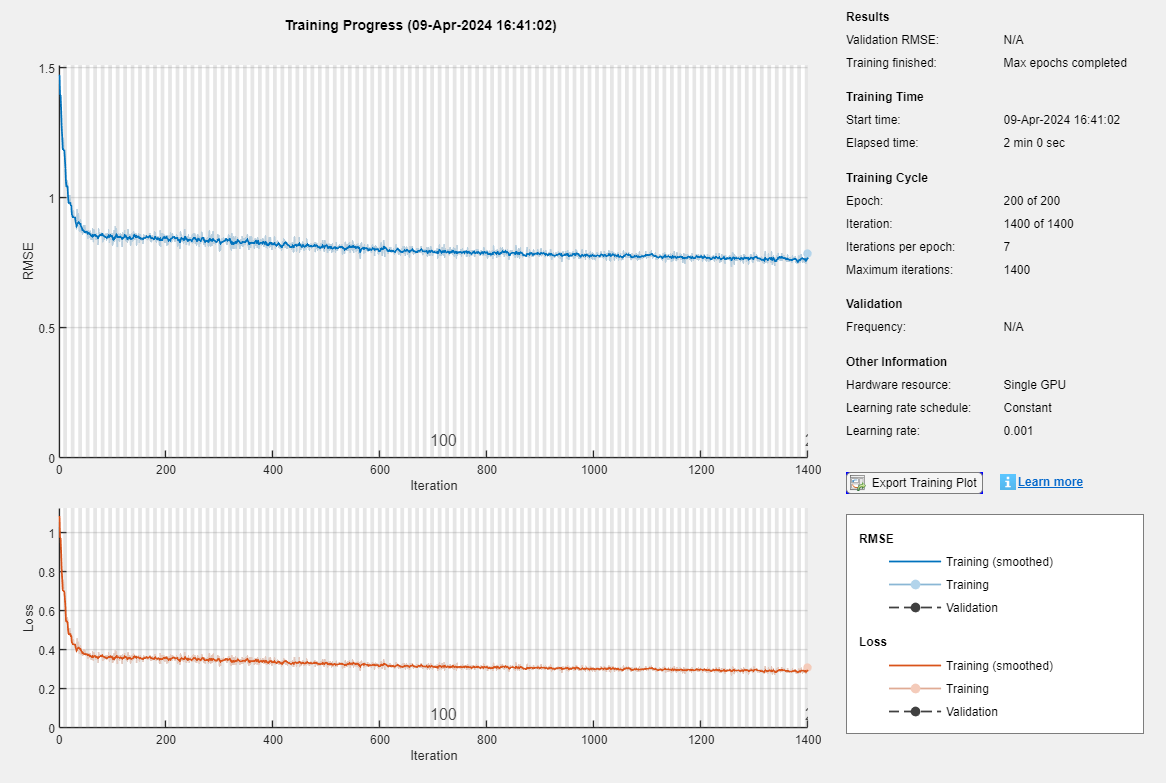

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options)

probar la red neuronal


for n = 1:size(dataTest,1)
    X = dataTest{n};
    XTest{n} = (X(:,1:end-1) - muX) ./ sigmaX;
    TTest{n} = (X(:,2:end) - muT) ./ sigmaT;
end

realizar la predicciones

YTest = predict(net,XTest,SequencePaddingDirection="left");


evaluar la presicion por medio del error medio cuadratico

for i = 1:size(YTest,1)
    rmse(i) = sqrt(mean((YTest{i} - TTest{i}).^2,"all"));
end

visualizar lor errores 

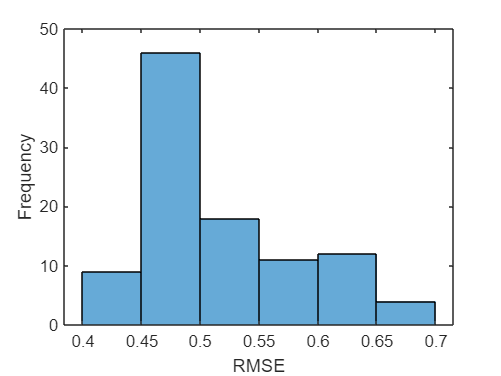

figure
histogram(rmse)
xlabel("RMSE")
ylabel("Frequency")

mean(rmse)

ans = single
0.5175

pronosticar valores

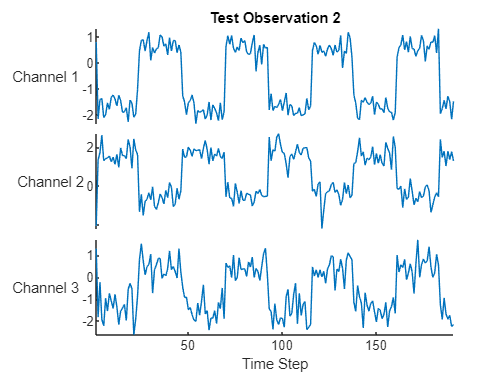

idx = 2;
X = XTest{idx};
T = TTest{idx};

figure
stackedplot(X',DisplayLabels="Channel " + (1:numChannels))
xlabel("Time Step")
title("Test Observation " + idx)